% Plot graphs
Plot = false;

% Determine where your m-file's folder is
folder = fileparts(which("opt_problem.mlx"));
% Add that folder plus all subfolders to the path
addpath(genpath(folder));

GFDM parameters

gfdm = struct;
gfdm.K = 13; % Subcarriers
gfdm.M = 7; % Subsymbols

gfdm.CP = 0; % CP length

Channel = 80; % Channel bandwidth (MHz)
B_low = Channel; % transmission bandwidth
B_up = 2*Channel;

gfdm = GFDM_init(gfdm);

D = gfdm.D;
D_prime = gfdm.D_prime;

All combinations of $K_{\mathrm{on}}$ and $M_{\mathrm{on}}$ with decreasing order: $N$

The number of element used $N_{\mathrm{sort}} \left(n\right)$ is the result of using $K_{\mathrm{on}}$ = $\mathrm{sort}\_\mathrm{idx}\_K\left(n\right)$ and $M_{\mathrm{on}}$ = $\mathrm{sort}\_\mathrm{idx}\_M\left(n\right)$.

% N(k,m) is the elements used for K_on=K and M_on=M
N = used_recources_chart(gfdm);

[N_sort, sort_idx_K, sort_idx_M] = sort_N(N, gfdm);

Normalized frequency $f$ and normalized frequency interval $\Delta f$

delta_f = 0.001;     % Normalized frequency: f = F/Fs = F/2B = F*Ts
f_range_end = 0.5;   % rc filter limit

% f_range_end should be divisible by delta_f
if mod(f_range_end,f_range_end)
    msg = 'normalized frequency sampling interval delta_f can not equally spaces f_range';
    error(msg);
end

f_range = [0 f_range_end];
f = -f_range(2):delta_f:f_range(2);

Interpolation filter $P(f)$

P = rc_filter(delta_f, f_range, 0.1);

Optimization problem & Dottorro iterative algorithm


$$\mathbf{S}=\mathbf{g}\mathbf{g}^H$$


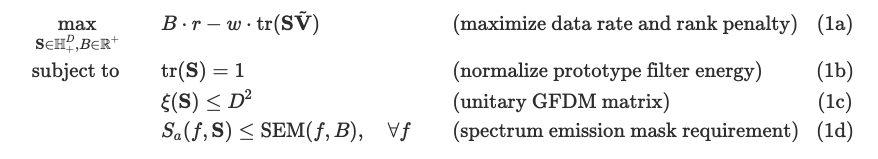

% Bisection stop criteria
B_criteria = 0.1;
B_diff = B_criteria;
B_mid = B_up;
while B_diff >= B_criteria
    fprintf('B = %f\n', B_mid);

    % Dottorro initialization
    s_2 = 1;
    V_tilde = zeros(D);
    problem_counter = 1;

    % Dottorro loop: solve the optimization problem until the second largest
    % singular value is small enough
    dottorro_start = tic;
    while abs(s_2) > 10^-6
        problem_start = tic;
        cvx_clear
        cvx_begin sdp quiet
        variable S(D, D) hermitian nonnegative semidefinite
        expression psd_temp(length(P), 1)

        % SEM
        mask_ac_dB = ac(delta_f, f_range, B_mid, Channel);
        mask_ac_linear = db2pow(mask_ac_dB);

        % PSD
        psd = (P.^2) .* PSD_S(gfdm, S, psd_temp, f_range, delta_f);

        minimize trace(S * V_tilde)          % (1a)
        subject to
        trace(S) == 1;                       % (1b)
        nep_S(S, gfdm.K, gfdm.M) <= D^2;     % (1c)
        psd <= mask_ac_linear;               % (1d)

        cvx_end
        fprintf('Problem time: %s\n', duration([0, 0, toc(problem_start)]));

$\tilde{\mathbf{V}}=\mathbf{U}\mathbf{U}^H, \mathbf{U} $ is $\mathbf{Q}$ with first column removed.

$\tilde{\mathbf{V}}$represents the (D-1)-dimensional space orthogonal to the principal eigenvector of $\mathbf{S}$ in the previous iteration.

        try
            [U_svd, S_svd, ~] = svd(S);
        catch ME
        end

        % Break the B increment loop if infeasible
        if isnan(S_svd(1, 1)) || problem_counter>=20
            fprintf('B = %f is INFEASIBLE.\n', B_mid);
            fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
            fprintf('===============================\n');
            
            % Bisection update if infeasible
            B_up = B_mid;
            break;
        end

        s_2 = S_svd(2, 2);
        fprintf('%d.s_2 = %f\n\n', problem_counter, s_2);

        U = U_svd(:, 2:end);
        V_tilde = U*U';

        problem_counter = problem_counter + 1;

Plot $S_a(f, \mathbf{S})$ and SEM

        if Plot == 1
            g = U_svd(:, 1) .* sqrt(S(1, 1));
            G = g2chaG(g, gfdm.K, gfdm.M);
            S_a = PSD(gfdm, G, f_range, delta_f);
            plot_PSD((P.^2) .* S_a, mask_ac_linear, f_range);
        end
    end

    if abs(s_2) < 10^-6
        S_solved = S;
        fprintf('%B = %f is feasible.\n', B_mid);
        fprintf('Dottorro time: %s\n', duration([0, 0, toc(dottorro_start)]));
        fprintf('===============================\n');

        % Bisection update if feasible
        B_low = B_mid;
        B = B_mid;

Obtain the GFDM prototype filter $\mathbf{g}$

        g = U_svd(:, 1) .* sqrt(S(1, 1));
        G = g2chaG(g, gfdm.K, gfdm.M);
        if Plot == 1
            S_a_S = PSD_S(gfdm, S, psd_temp, f_range, delta_f);
            plot_PSD((P.^2) .* S_a_S, mask_ac_linear, f_range);
        end
    end
    
    B_diff = B_up - B_low;
    % Midpoint
    B_mid = (B_up + B_low)/2;
end

 
mask_ac_dB = ac(delta_f, f_range, B, Cnannel);
mask_ac_linear = db2pow(mask_ac_dB);
psd_temp = zeros(size(P));
% S_a = PSD(gfdm, G, f_range, delta_f);
S_a_S = PSD_S(gfdm, S_solved, psd_temp, f_range, delta_f);
plot_PSD((P.^2) .* S_a_S, mask_ac_linear, f_range);
title(['B=', num2str(B)]);
text(-0.2, -50, ['$K=$' num2str(gfdm.K) ', $M=$' num2str(gfdm.M)], 'interpreter','latex');
text(-0.2, -55, ['$K_{on}=$' num2str(gfdm.K_on) ', $M_{on}=$' num2str(gfdm.M_on)], 'interpreter','latex');